annotation_dir = "/home/akamath/Documents/miccaihackathon_shifts/data/mean_annotators/";
output_dir = "/home/akamath/Documents/miccaihackathon_shifts/data/output_annotation_histograms/";
mkdir(output_dir)

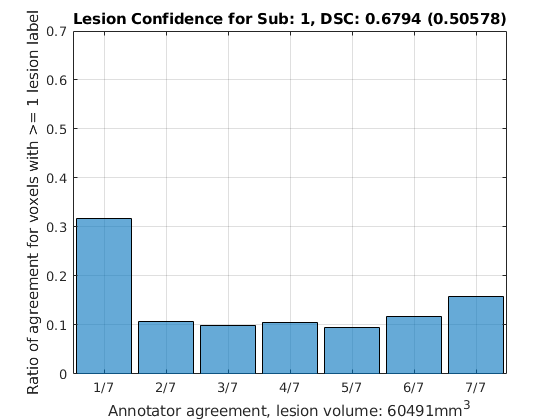

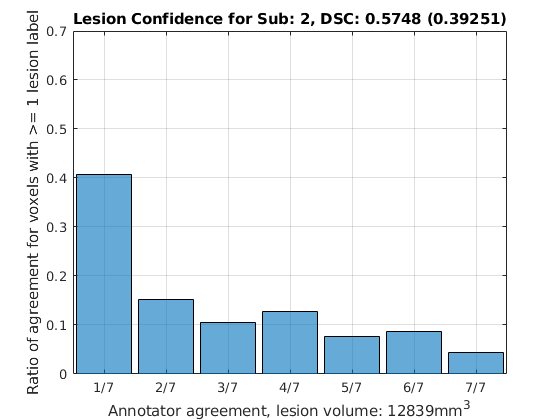

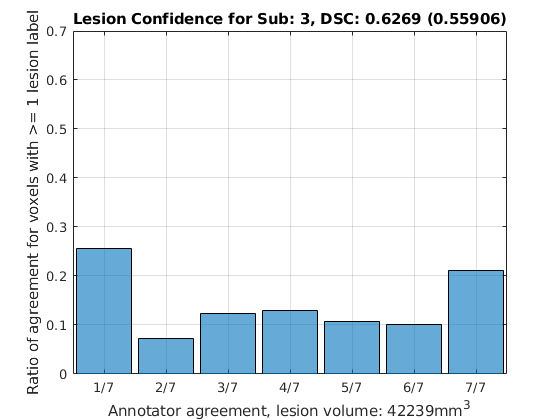

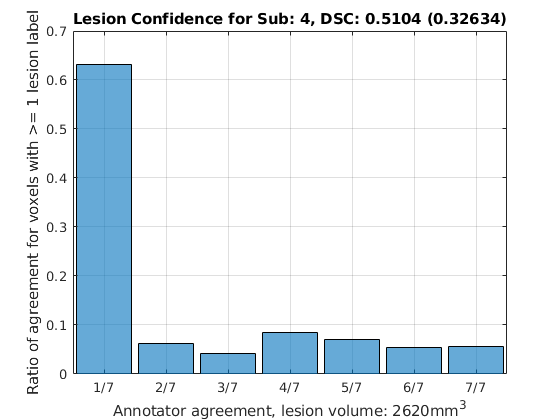

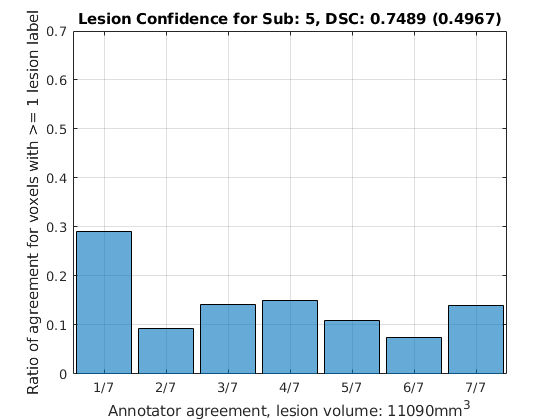

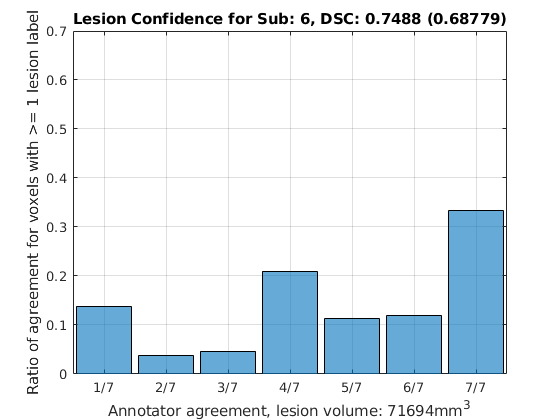

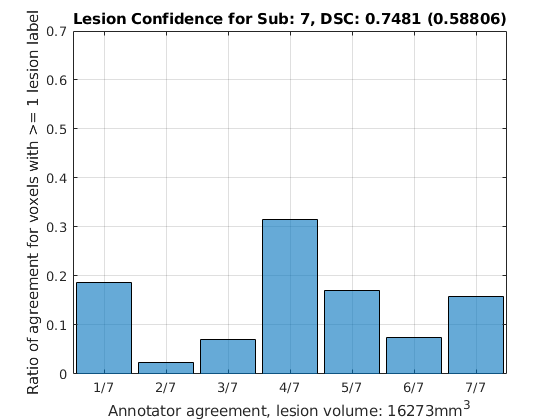

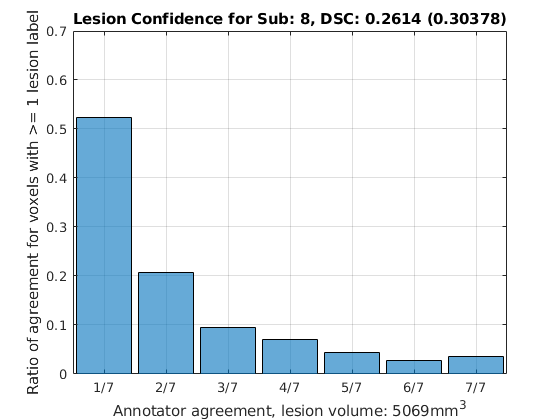


dsc = [0.6794, 0.5748, 0.6269, 0.5104, 0.7489, 0.7488, 0.7481, 0.2614, 0.7433, 0.7599, 0.7212, 0.5062, 0.5651, 0.5859, 0.7458, 0.8318, 0.6587, 0.3749, 0.6348, 0.1528, 0.7919, 0.8623, 0.8335, 0.7129];

% This is a quick and dirty way to aggregate the histogram numbers to come
% up with a single confidence number.
lesion_confidence = [];
total_lesion_volume = [];
weights = 1:7;

for idx = 1:24
    mean_ann_for_subject = fullfile(annotation_dir, string(idx) + "_mean_annotation.nii.gz");
    mean_data = niftiread(mean_ann_for_subject);
    lesion_volume = sum(mean_data > 0, 'all');
    mean_cat = categorical(mean_data(mean_data > 0), unique(mean_data(mean_data > 0)), ["1/7", "2/7", "3/7", "4/7", "5/7", "6/7", "7/7"]);
    figure, 
    fig = histogram(mean_cat, 'Normalization', 'probability');
    conf = sum(fig.Values .* weights)/7;
    lesion_confidence = [lesion_confidence, conf];
    total_lesion_volume = [total_lesion_volume, lesion_volume];
    title("Lesion Confidence for Sub: " + string(idx) + ", DSC: " + string(dsc(idx)) + " (" + string(conf) + ")");
    ylabel('Ratio of agreement for voxels with >= 1 lesion label')
    xlabel("Annotator agreement, lesion volume: " + string(lesion_volume) + "mm^3")
    grid on
    ylim([0.0 0.7])
    saveas(fig, fullfile(output_dir, string(idx) + "_histogram.png"));
end

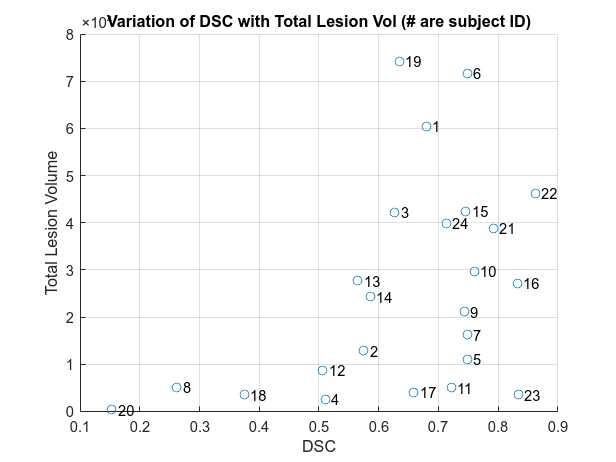

scatter(dsc, total_lesion_volume)
grid on
xlabel("DSC")
ylabel("Total Lesion Volume")
title("Variation of DSC with Total Lesion Vol (# are subject ID)")

for idx = 1:24
    dx = 0.01; dy = 0.01; % displacement so the text does not overlay the data points
    text(dsc(idx)+dx, total_lesion_volume(idx)+dy, string(idx));
end


corrcoef(dsc, total_lesion_volume)

ans =     1.0000    0.4249
    0.4249    1.0000


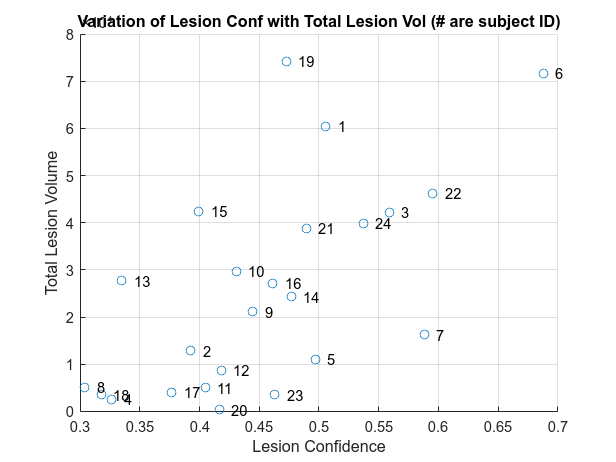

scatter(lesion_confidence, total_lesion_volume)
grid on
xlabel("Lesion Confidence")
ylabel("Total Lesion Volume")
title("Variation of Lesion Conf with Total Lesion Vol (# are subject ID)")

for idx = 1:24
    dx = 0.01; dy = 0.01; % displacement so the text does not overlay the data points
    text(lesion_confidence(idx)+dx, total_lesion_volume(idx)+dy, string(idx));
end

corrcoef(lesion_confidence, total_lesion_volume)

ans =     1.0000    0.6305
    0.6305    1.0000


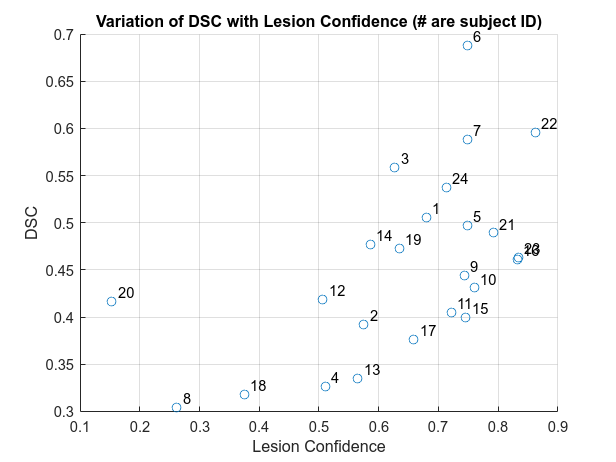

scatter(dsc, lesion_confidence)
grid on
xlabel("Lesion Confidence")
ylabel("DSC")
title("Variation of DSC with Lesion Confidence (# are subject ID)")

for idx = 1:24
    dx = 0.01; dy = 0.01; % displacement so the text does not overlay the data points
    text(dsc(idx)+dx, lesion_confidence(idx)+dy, string(idx));
end

corrcoef(dsc, lesion_confidence)

ans =     1.0000    0.5663
    0.5663    1.0000
